# Problem 1

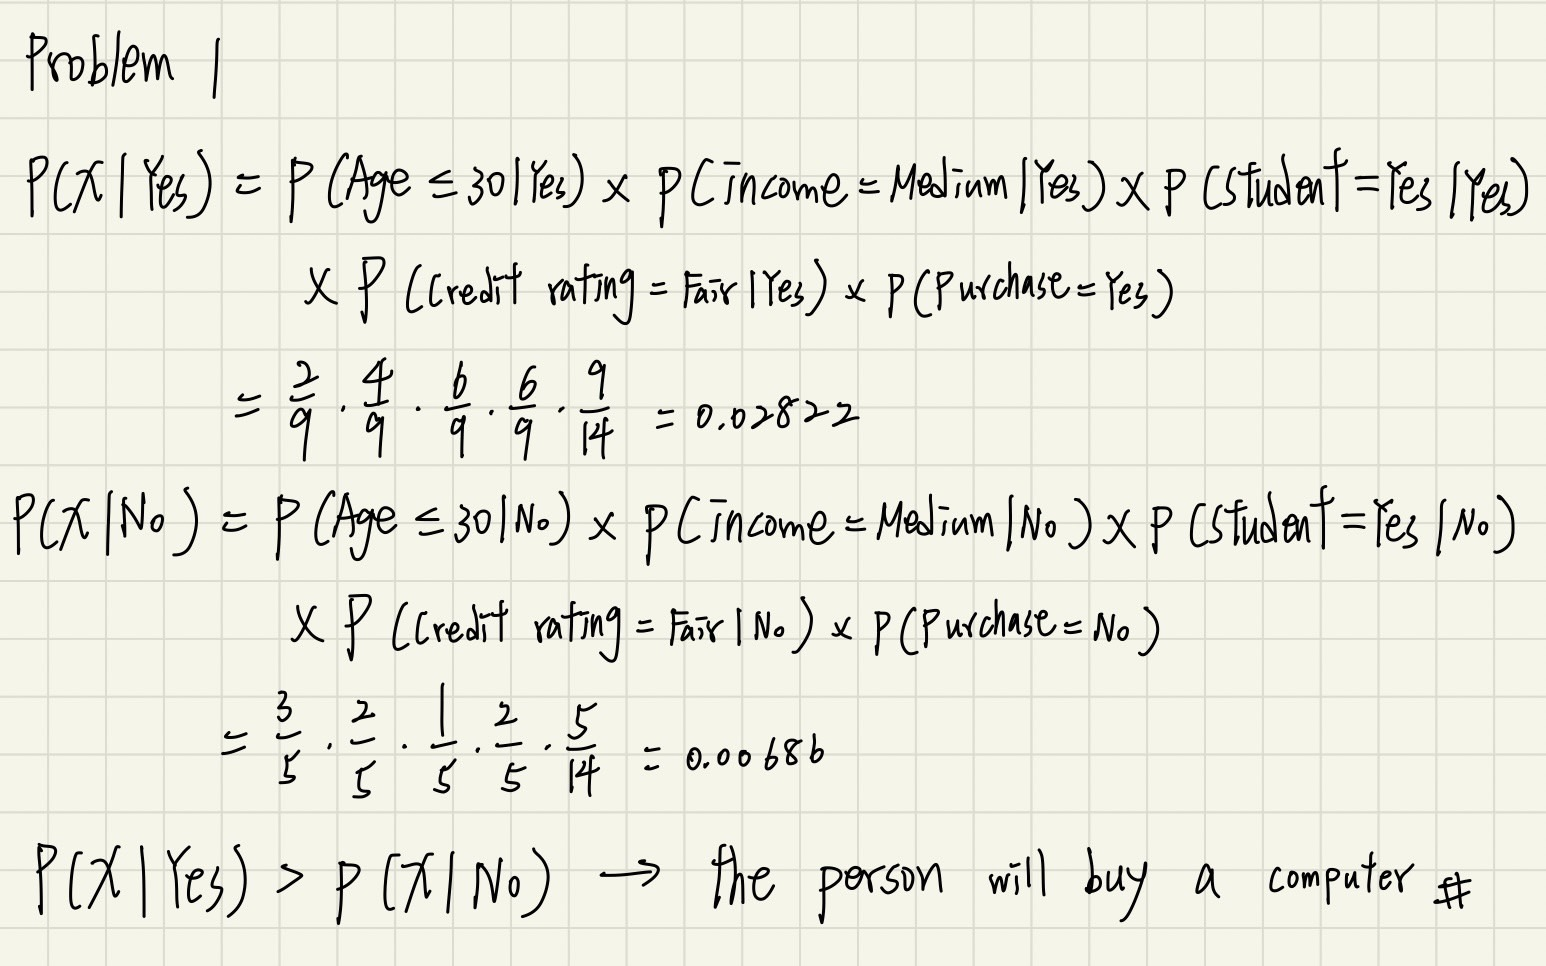

# Problem 2

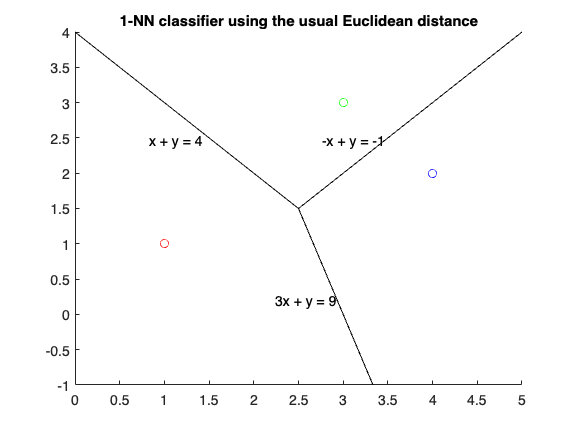

clear;
% (a)Labelled training data points
x = [1 3 4;1 3 2];
y = [1 2 3];
[vx,vy] = voronoi(x(1,:),x(2,:)); 
figure;
hold on;
plot(vx,vy,'k-');
plot(x(1,1),x(2,1),'ro');
plot(x(1,2),x(2,2),'go');
plot(x(1,3),x(2,3),'bo');
xlim([0 5]); ylim([-1 4]);

for i = 1:length(y)
    vb = polyfit(vx(:,i),vy(:,i),1);
    if num2str(-vb(1))=='-1'
        eq = [ '-x + y = ' num2str(vb(2))];
    elseif num2str(-vb(1))=='1'
        eq = [ 'x + y = ' num2str(vb(2))];
    else
        eq = [num2str(-vb(1)) 'x + y = ' num2str(vb(2))];
    end
    text((vx(1,i)*2+vx(2,i))/3-0.7,(vy(1,i)*2+vy(2,i))/3,eq);  
end
title('1-NN classifier using the usual Euclidean distance');
hold off;

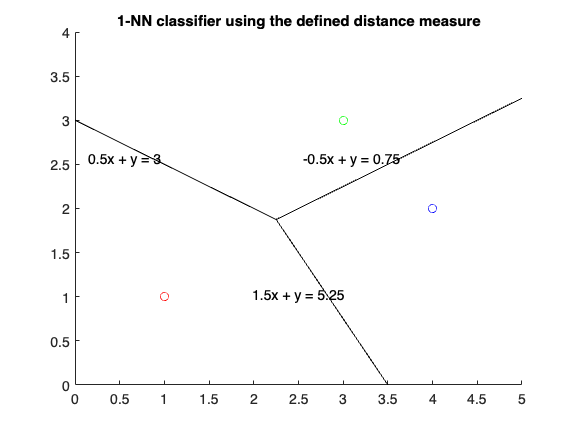

% (b)Defined distance measure
[vx,vy] = voronoi(x(1,:)/sqrt(2),x(2,:));
vx = vx*sqrt(2);
figure;
hold on;
plot(vx,vy,'k-');
plot(x(1,1),x(2,1),'ro');
plot(x(1,2),x(2,2),'go');
plot(x(1,3),x(2,3),'bo');
xlim([0 5]); ylim([0 4]);

for i = 1:length(y)
    vb = polyfit(vx(:,i),vy(:,i),1);
    eq = [num2str(-vb(1)) 'x + y = ' num2str(vb(2))];
    text((vx(1,i)*2+vx(2,i))/3-0.9,(vy(1,i)*2+vy(2,i))/3+0.1,eq);
end
title('1-NN classifier using the defined distance measure');
hold off;

# Problem 3

clear;
% load data
train = load('10HW3_train.txt');
test = load('10HW3_test.txt');
val = load('10HW3_validate.txt');
train_x = train(:,1:784); 
train_y = train(:,785);
test_x = test(:,1:784); 
test_y = test(:,785);
val_x = val(:,1:784); 
val_y = val(:,785);

% (a)For k = 1, 3, 5, 11, 16, and 21, build kNN classifiers
k = [1 3 5 11 16 21];
training_err = zeros(1,6); 
validation_err = zeros(1,6); 
test_err = zeros(1,6);

for i = 1:6
    MD = fitcknn(train_x,train_y,'NumNeighbors',k(i));
    pred_train = predict(MD,train_x);
    pred_val = predict(MD,val_x);
    pred_test = predict(MD,test_x); 
    err_teain = ((pred_train-train_y) ~= 0); 
    training_err(i) = sum(sum(err_teain))/1000;
    err_val = ((pred_val-val_y) ~= 0); 
    validation_err(i) = sum(sum(err_val))/300;
    err_test = ((pred_test-test_y) ~= 0); 
    test_err(i) = sum(sum(err_test))/300;
end

min_err_val=inf;
for i=1:6
    if validation_err(i)<min_err_val
        min_err_val=validation_err(i);
        min_val_k=i;
    end
end

fprintf(['Training  error for  k=[1 3 5 11 16 21] = [%s        %s    %s  %s    %s    %s  ]\n' ...
    'Validation error for k=[1 3 5 11 16 21] = [%s  %s  %s   %s  %s  %s]' ...
    '\nk=%s performs the best on validation data.' ...
    '\nTest error(k=%s) = %s'],num2str(training_err(1)),num2str(training_err(2)),num2str(training_err(3)),num2str(training_err(4)),num2str(training_err(5)),num2str(training_err(6)),num2str(validation_err(1)),num2str(validation_err(2)),num2str(validation_err(3)),num2str(validation_err(4)),num2str(validation_err(5)),num2str(validation_err(6)),num2str(min_val_k),num2str(min_val_k),num2str(test_err(min_val_k)));

Training  error for  k=[1 3 5 11 16 21] = [0        0.067    0.084  0.116    0.137    0.154  ]
Validation error for k=[1 3 5 11 16 21] = [0.12667  0.14333  0.13   0.17333  0.19667  0.20333]
k=1 performs the best on validation data.
Test error(k=1) = 0.10667

% (b)3-NN classifier
MD_3NN = fitcknn(train_x,train_y,'NumNeighbors',3);
pred = predict(MD_3NN,test_x);
confusion_m = confusionmat(test_y,pred)'; 
for j = 1:10
    S = sum(confusion_m(:,j)); 
    confusion_m(:,j) = confusion_m(:,j)/S;
end

HTC=inf;
for i=1:10
    if confusion_m(i,i)<HTC
        HTC=confusion_m(i,i);
        HTC_n=i-1;
    end
end
ETC=0;
for i=1:10
    if confusion_m(i,i)>ETC
        ETC=confusion_m(i,i);
        ETC_n=i-1;
    end
end
fprintf(['confusion matrix: ' ...
    '\n         0           1           2           3           4           5           6           7           8           9' ...
    '\n0  %s\n1        %s\n2        %s\n3        %s\n4        %s\n5        %s\n6  %s\n7        %s\n8        %s\n9        %s' ...
    '\n' ...
    '\n%s is easiest to classify.' ...
    '\n%s is hardest to classify.'],num2str(confusion_m(1,:)),num2str(confusion_m(2,:)),num2str(confusion_m(3,:)),num2str(confusion_m(4,:)),num2str(confusion_m(5,:)),num2str(confusion_m(6,:)),num2str(confusion_m(7,:)),num2str(confusion_m(8,:)),num2str(confusion_m(9,:)),num2str(confusion_m(10,:)),num2str(ETC_n),num2str(HTC_n));

confusion matrix: 
         0           1           2           3           4           5           6           7           8           9
0  0.89286           0           0           0           0           0           0           0           0           0
1        0           1    0.052632     0.13333           0           0    0.054054           0           0           0
2        0           0     0.92105    0.033333           0           0           0           0           0    0.037037
3        0           0           0     0.76667           0    0.076923           0           0    0.035714           0
4        0           0           0           0     0.92857           0           0           0           0    0.037037
5        0           0           0           0           0     0.84615    0.027027           0           0           0
6  0.10714           0           0           0           0           0     0.91892           0    0.035714           0
7        0           0       

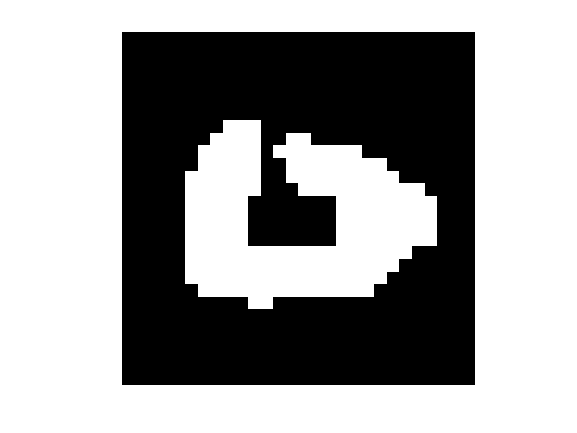

% (c)Identify one falsely classified vector, convert the vector back to a 28x28 image.
falsely = find(pred ~= test_y); 
I=test_x(falsely(4),:);
I = reshape(I,28,28)';
figure;
imshow(I);

fprintf('The image labeled %s is predicted as %s.',num2str(test_y(falsely(i))),num2str(pred(falsely(i))));

The image labeled 0 is predicted as 6.

    k-NN model 無法準確判斷該圖片特徵為0或是6。